% Code to plot simulation results from GreenHydrogenMicrogrid

## Plot Description:

The plot below shows the power of the electrolyzer, solar and storage system, battery state of charge, and produced hydrogen.

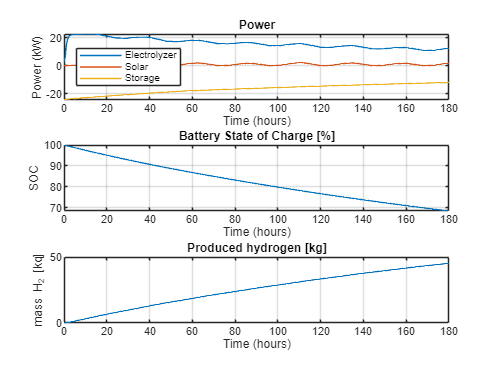

% Generate simulation results if they don't exist
if ~exist('simlog_GreenHydrogenMicrogrid', 'var') || ...
        simlogNeedsUpdate(simlog_GreenHydrogenMicrogrid, 'GreenHydrogenMicrogrid')
    sim('GreenHydrogenMicrogrid')
    % Model StopFcn callback adds a timestamp to the Simscape simulation data log
end

% Reuse figure if it exists, else create new figure
if ~exist('h1_GreenHydrogenMicrogrid', 'var') || ...
        ~isgraphics(h1_GreenHydrogenMicrogrid, 'figure')
    h1_GreenHydrogenMicrogrid = figure('Name', 'GreenHydrogenMicrogrid');
end
figure(h1_GreenHydrogenMicrogrid)
clf(h1_GreenHydrogenMicrogrid)

% Get simulation results
simlog_PElectrolyzer = logsout_GreenHydrogenMicrogrid.get('PElectrolyzer');
simlog_PSolar = logsout_GreenHydrogenMicrogrid.get('PSolar');
simlog_PStorage = logsout_GreenHydrogenMicrogrid.get('PStorage');
simlog_SOC = logsout_GreenHydrogenMicrogrid.get('SOC');
simlog_mH2 = logsout_GreenHydrogenMicrogrid.get('mH2');

% Plot results
simlog_handles(1) = subplot(3, 1, 1);
plot(simlog_PElectrolyzer.Values.Time/3600, simlog_PElectrolyzer.Values.Data, 'LineWidth', 1)
hold on
plot(simlog_PSolar.Values.Time/3600, simlog_PSolar.Values.Data, 'LineWidth', 1)
plot(simlog_PStorage.Values.Time/3600, simlog_PStorage.Values.Data, 'LineWidth', 1)
hold off
grid on
title('Power')
ylabel('Power (kW)')
xlabel('Time (hours)')
legend({'Electrolyzer','Solar','Storage'},'Location','Best');

simlog_handles(2) = subplot(3, 1, 2);
plot(simlog_SOC.Values.Time/3600, simlog_SOC.Values.Data, 'LineWidth', 1)
hold off
grid on
title('Battery State of Charge [%]')
ylabel('SOC')
xlabel('Time (hours)')

simlog_handles(3) = subplot(3, 1, 3);
plot(simlog_mH2.Values.Time/3600, simlog_mH2.Values.Data, 'LineWidth', 1)
grid on
title('Produced hydrogen [kg]')
ylabel('mass H_2 [kq]')
xlabel('Time (hours)')


linkaxes(simlog_handles, 'x')


% Remove temporary variables
clear simlog_handles temp_colororder
clear simlog_PElectrolyzer simlog_PSolar simlog_PStorage simlog_SOC simlog_mH2

*Copyright 2018-2023 The MathWorks, Inc.*